# Running MONAI model inference in MATLAB

terminate(pyenv)
pyversion('/Users/amithkamath/opt/anaconda3/envs/matlab-env/bin/python')
py.importlib.import_module('monaiInference');

<frozen importlib._bootstrap>:228: UserWarning: Invalid MKL_NUM_THREADS variable value, stoi: no conversion (Triggered internally at /private/var/folders/sy/f16zz6x50xz3113nwtb9bvq00000gp/T/abs_9d63z49rj_/croot/pytorch_1681837279022/work/aten/src/ATen/ParallelCommon.cpp:38.)
/Users/amithkamath/opt/anaconda3/envs/matlab-env/lib/python3.9/site-packages/torchvision/io/image.py:13: UserWarning: Failed to load image Python extension: dlopen(/Users/amithkamath/opt/anaconda3/envs/matlab-env/lib/python3.9/site-packages/torchvision/image.so, 0x0006): Symbol not found: __ZN2at4_ops19empty_memory_format4callEN3c108ArrayRefIxEENS2_8optionalINS2_10ScalarTypeEEENS5_INS2_6LayoutEEENS5_INS2_6DeviceEEENS5_IbEENS5_INS2_12MemoryFormatEEE
  Referenced from: <67CD63CE-57E0-341F-B3B8-78729B03D2B3> /Users/amithkamath/opt/anaconda3/envs/matlab-env/lib/python3.9/site-packages/torchvision/image.so
  Expected in:     <908CA0CD-2294-3FE1-BD48-F54A78458210> /Users/amithkamath/opt/anaconda3/envs/matlab-env/lib/pyth

monaiUNet = py.monaiInference.create_model("heart-2d-model.pth")

monaiUNet =   Python UNet with properties:

    up_kernel_size: [1×1 py.int]
        dimensions: [1×1 py.int]
              bias: 0
       in_channels: [1×1 py.int]
              norm: [1×5 py.str]
               act: [1×4 py.str]
      adn_ordering: [1×3 py.str]
           strides: [1×5 py.tuple]
          training: 1
     num_res_units: [1×1 py.int]
          channels: [1×6 py.tuple]
           dropout: 0
       kernel_size: [1×1 py.int]
      out_channels: [1×1 py.int]

    UNet(
      (model): Sequential(
        (0): Convolution(
          (conv): Conv2d(1, 16, kernel_size=(3, 3), stride=(2, 2), padding=(1, 1), bias=False)
          (adn): ADN(
            (N): BatchNorm2d(16, eps=1e-05, momentum=0.1, affine=True, track_running_stats=True)
            (D): Dropout(p=0.0, inplace=False)
            (A): ReLU()
          )
        )
        (1): SkipConnection(
          (submodule): Sequential(

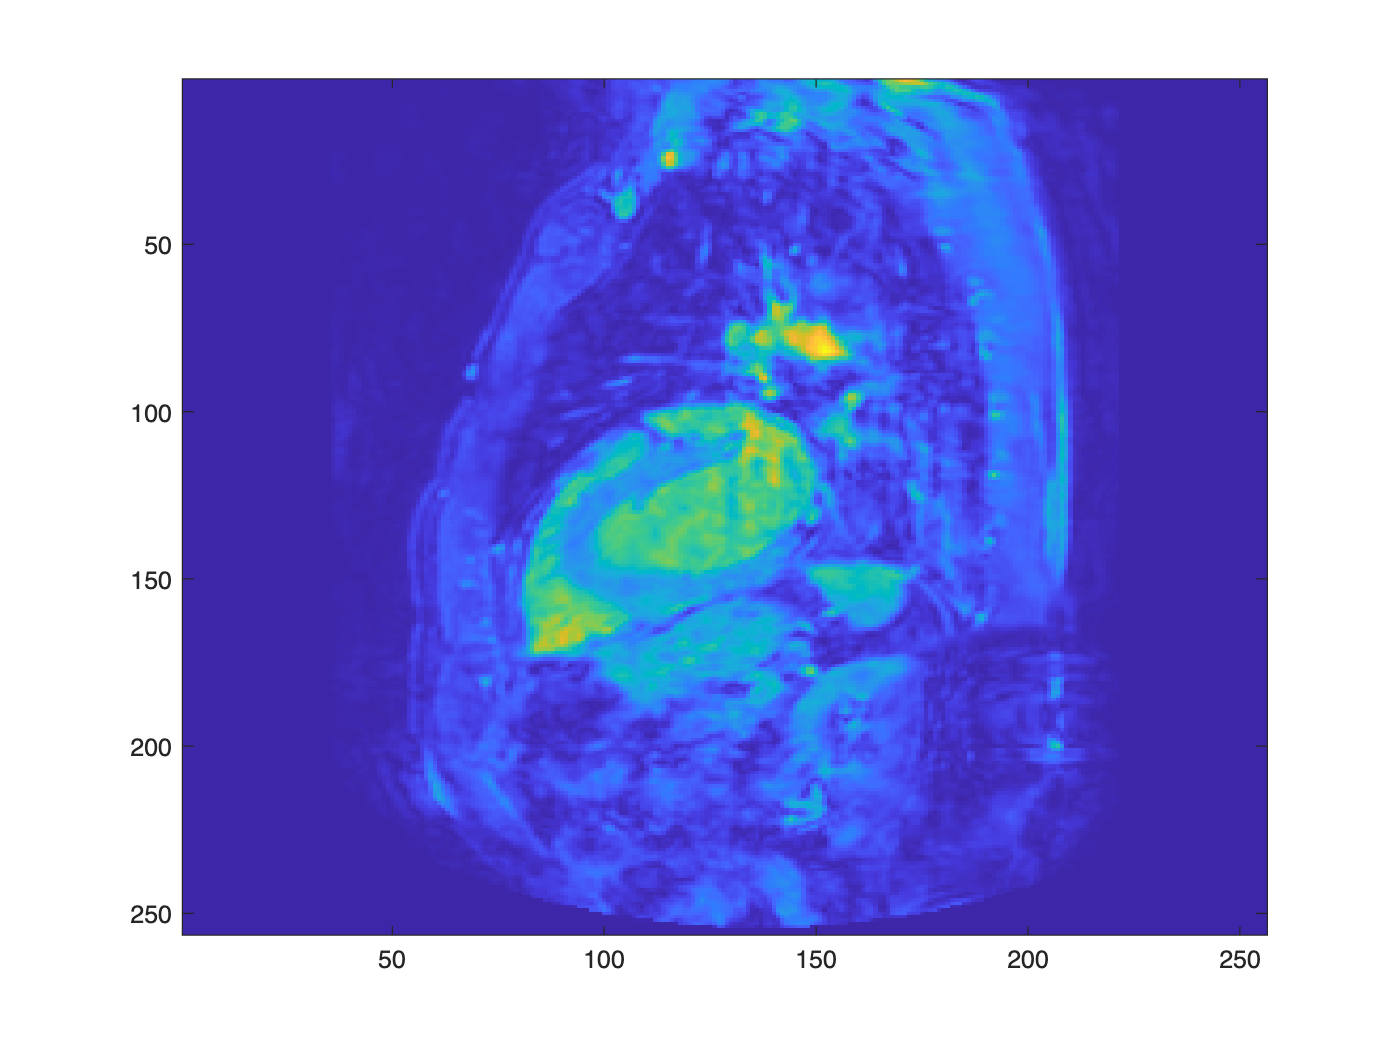

im = imread("data/images/image_0000.png");
imagesc(im)

im_channel = single(reshape(im, [1, 1, 256, 256]));
im_channel = im_channel ./ 255;

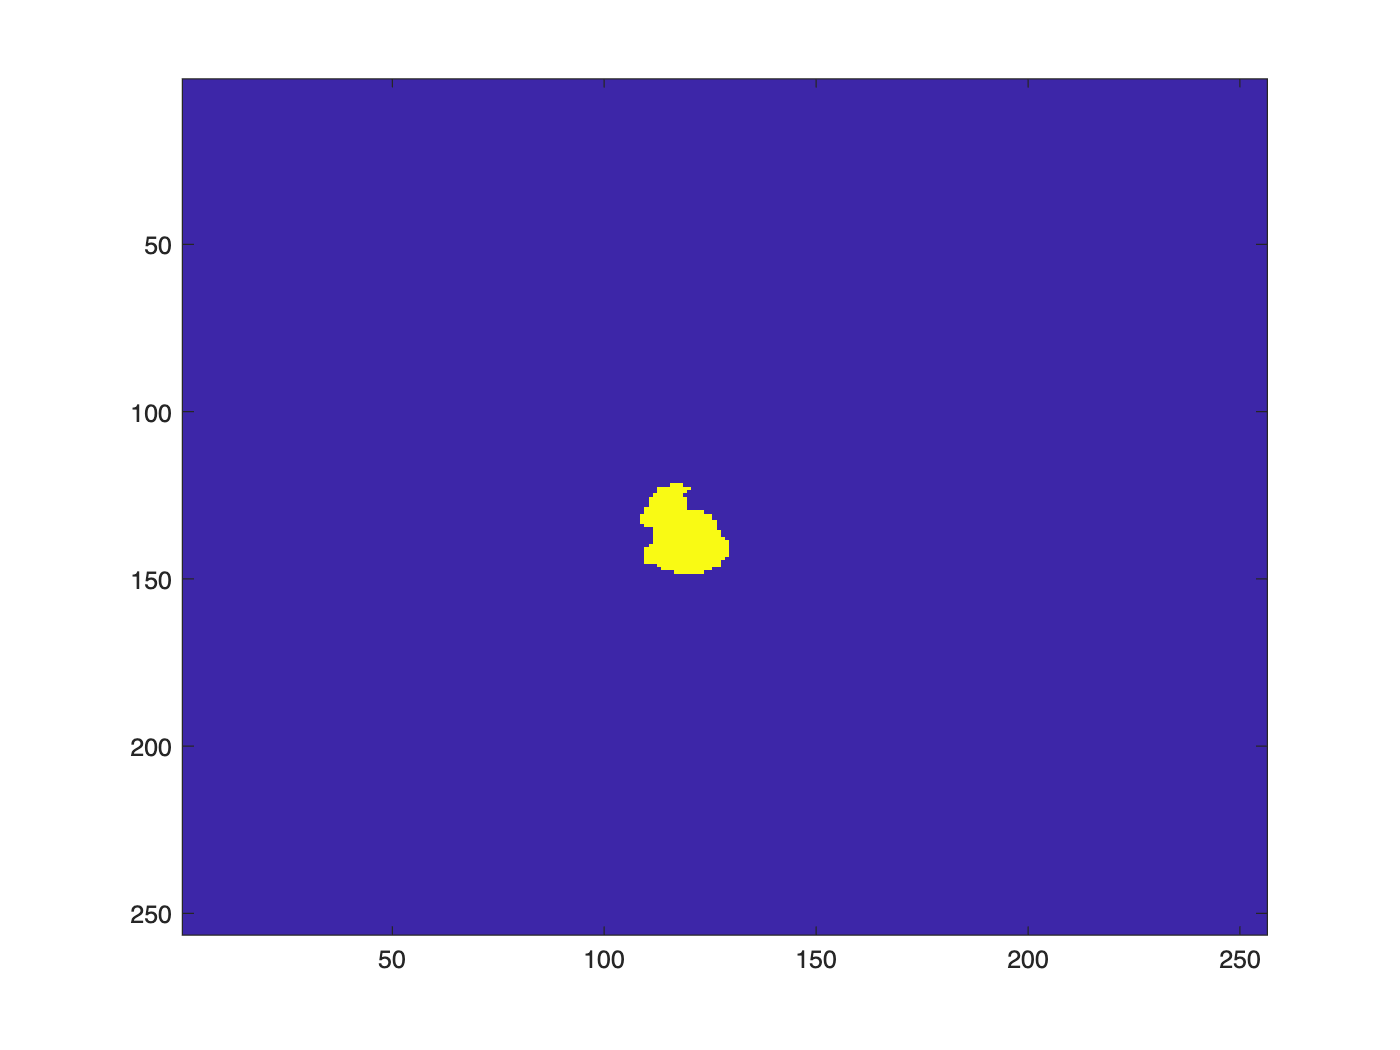

seg = py.monaiInference.inference(monaiUNet, py.torch.tensor(py.numpy.array(im_channel)));
seg = squeeze(single(py.numpy.array(seg)));
imagesc(seg)